# Control de sistemas biológicos TP N°1

A continuación se resuelve el problema 1 de la práctica N°1.

El modelo a controlar es el siguiente:

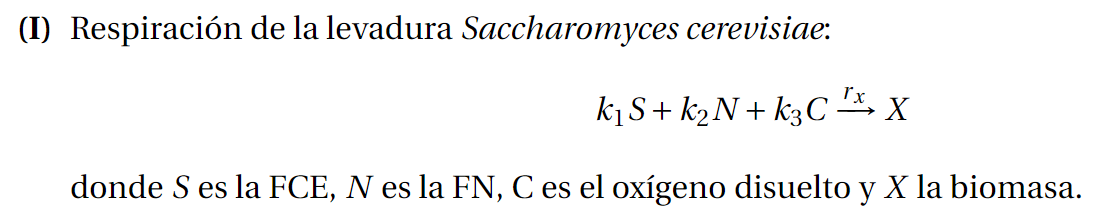

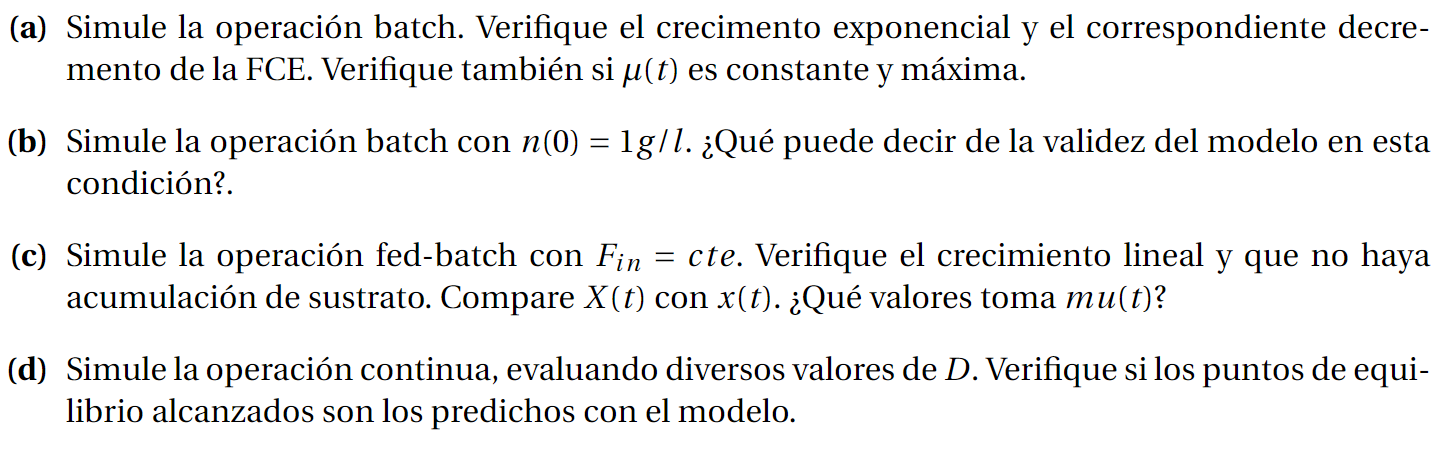

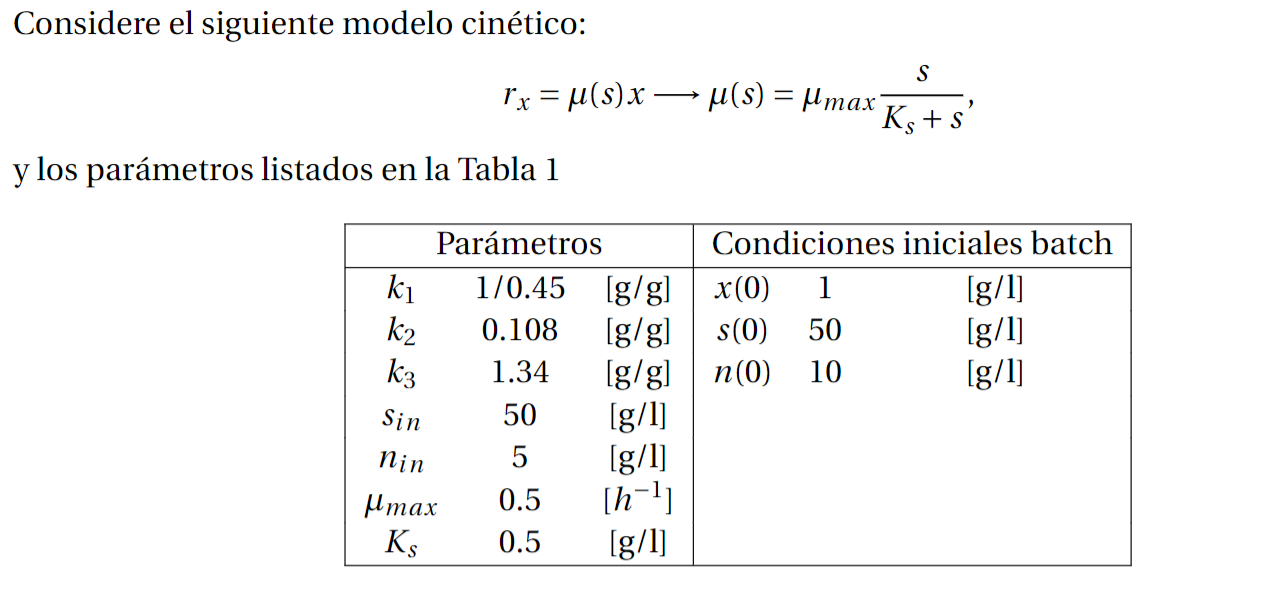

clc; clear all;

## Preguntas

- El modelo que me dá el factor de reacción (Monod por ejemplo) es sólamente una relación entre sustrato y el factor de reacción?

Defino los parámetros del modelo para un batch con modelo de Monod

% Definimos parámetros del modelo
mumax=0.5;
Ks=0.5;
k1=1/0.45;
k2=0.108;
k3=1.34;
% K=[1;-0.4];
K=[1 -k1 -k2 -k3];
% result = K * r + D * xi_in - D * xi;

% Creamos una estructura para pasar los parámetros al bloque función u
% otros bloques
parametrosModelo.mumax=mumax;
parametrosModelo.Ks=Ks;
parametrosModelo.K=K;

% Definimos entradas y condiciones iniciales
xi_in=[0;50;5;8];
D=0.1;
xi0=[1;50;10;1e3];

simConfig.StopTime = "50";
sim_out = sim('TP1\basicModelWithMonod.slx', simConfig);

Error due to multiple causes.

Caused by:
    Error using TP1 (line 24)
    Error in port widths or dimensions. 'Output Port 1' of 'basicModelWithMonod/MATLAB Function' is a [4x4] matrix.
    Error using TP1 (

Grafico los resultados de la simulación

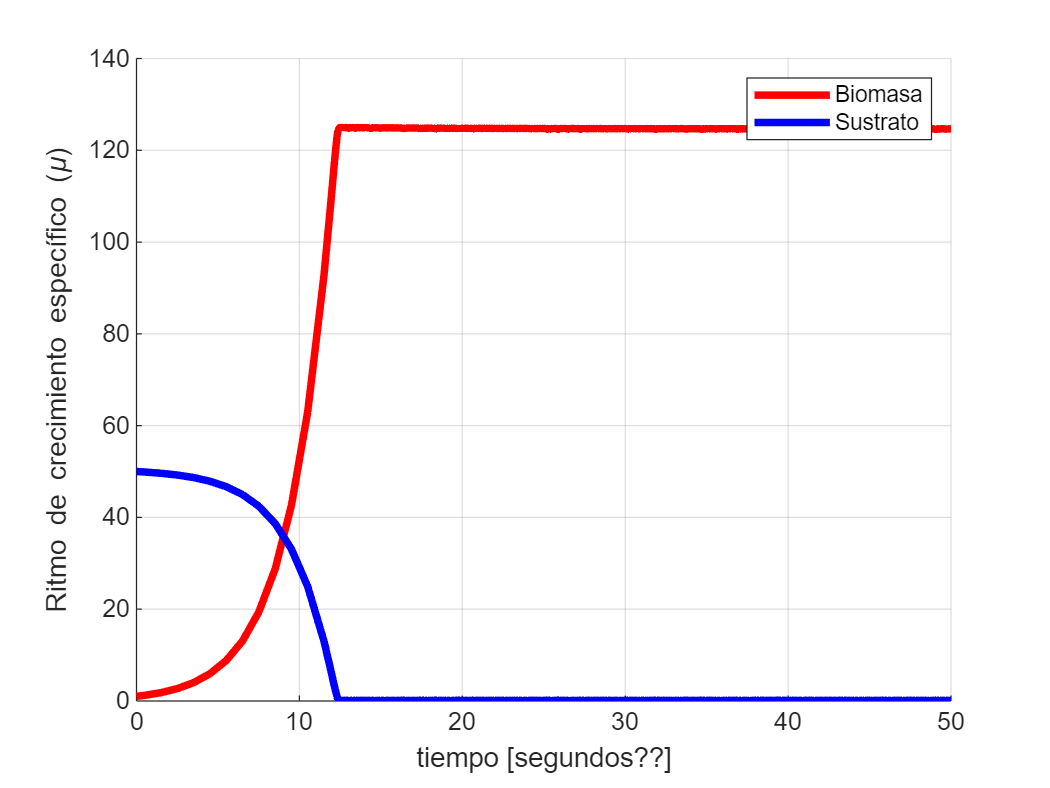

time = sim_out.simout.Time;
biomass = reshape(sim_out.simout.Data(1,1,:), size(time));
sustrate = reshape(sim_out.simout.Data(2,1,:), size(time));

fig = figure();
hold on; grid on;
xlabel('tiempo [Horas]');
ylabel('Ritmo de crecimiento específico (\mu)');

plot(time, biomass, 'r', 'LineWidth', 3);
plot(time, sustrate, 'b', 'LineWidth', 3);

legend('Biomasa', 'Sustrato');